
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
droneSpeed = 0.1; 
timeStep = 5; 

% Chaser initial position. 
x_c_0 = [-1; 0]; 

% Evader initial states. 
x_e_0 = [0; 0; 0; droneSpeed]; 

% Position constraints. 
positionBounds = [-1; 1; -1; 1]*50; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
guess = [ ...
    x_c_0(1)+timeStep*x_e_0(3); ...
    x_c_0(2)+timeStep*x_e_0(4); ...
    x_c_0(1)+timeStep*x_e_0(3) - (x_e_0(1)+timeStep*x_e_0(3)); ...
    x_c_0(2)+timeStep*x_e_0(4) - (x_e_0(2)+timeStep*x_e_0(4))]; 

solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, droneSpeed), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b,  x_c_0, x_e_0, timeStep), ...
    solGuess, options); 

The solution was obtained on a mesh of 501 points.
The maximum residual is  6.931e-06. 
There were 10124 calls to the ODE function. 
There were 28 calls to the BC function. 


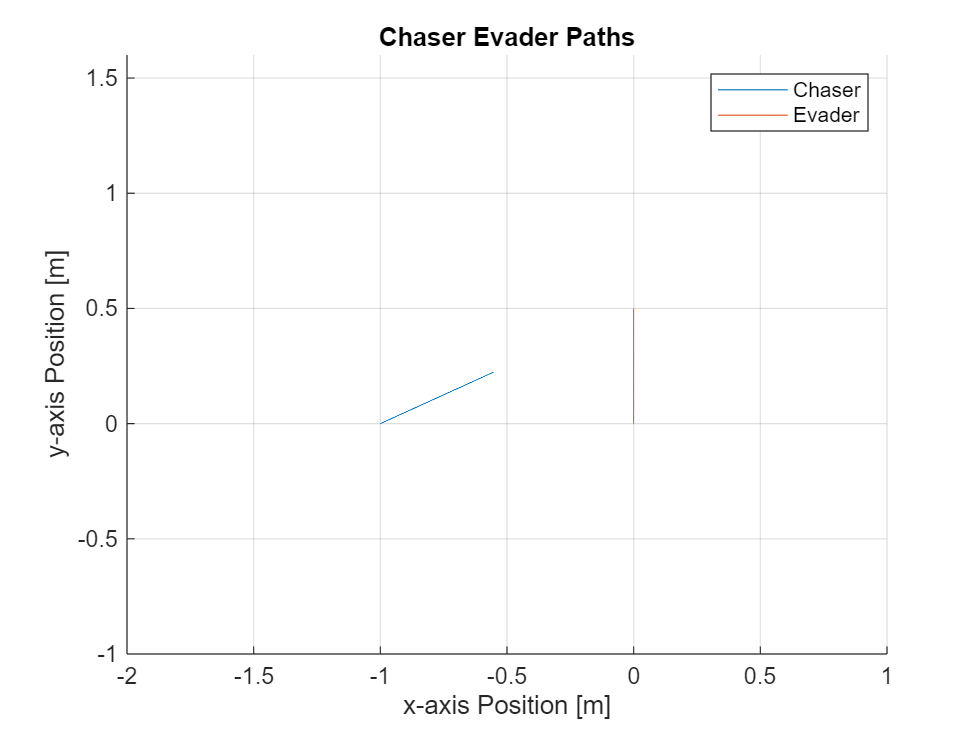

tspan = sol.x; 
y = sol.y; 

clf; 
hold on; 
grid on; 
plot( ...
    y(1, :), y(2, :), ...
    x_e_0(1)+tspan*x_e_0(3), x_e_0(2)+tspan*x_e_0(4)); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
axis([-2 1 -1 1.6]); 
hold off; 

% Differential equations. 
function dydt = eqns(~, y, chaserSpeed)
    % Optimal control. 
    u = atan2(y(4), y(3))+pi; 

    dydt = [chaserSpeed*cos(u); chaserSpeed*sin(u); 0; 0]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, x_c_0, x_e_0, timeStep)
    retval = [ ...
        y_a(1) - x_c_0(1); ...
        y_a(2) - x_c_0(2); ...
        y_b(3) - (y_b(1) - (x_e_0(1)+timeStep*x_e_0(3))); ...
        y_b(4) - (y_b(2) - (x_e_0(2)+timeStep*x_e_0(4)))]; 
end